## 1. Construct an input space consisting of the polynomials *x^*0, *x^*1, *x^*2, *x^*3, and *x^*4 evaluated over the range[–1,1]. Then generate a weighted sum of these polynomials using random weights (e.g. `randn`). Repeat this a total of 20 times and visualize the results.

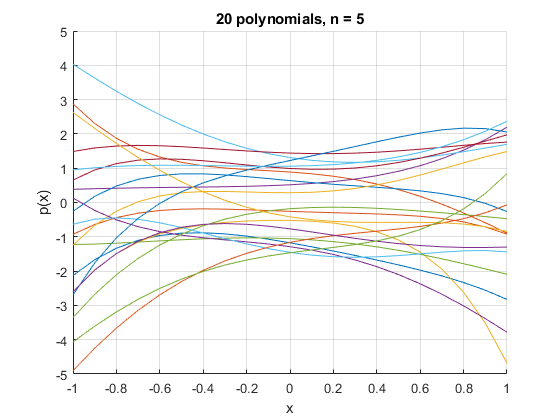

repeatCount = 20;
pDegree = 5;

% construct an input space with polynomials
% evaluated over the range [-1;1] with a step 0.1
xVals = -1:.1:1;

% p represents the following polynomial:
% p(x) = randn()*x^4 + randn()*x^3 + randn()*x^2 + randn()*x - randn();
% the random weights of polynomial are normally distributed values;
% p coontains 20 weight-vectors (one row - one polynomial)
p = randn(20, pDegree);

figure;
hold on;
grid;
xlabel('x');
ylabel('p(x)');
title(sprintf('20 polynomials, n = %d', pDegree));
% polyval - evaluates the polynomial p at each point of input interval x
for i = 1 : repeatCount
    plot(xVals, polyval(p(i,:), xVals));
end

## 2. Generate some random data using `rand(1,100).^4`. We want to find a value that summarizes the central tendency of these data, and suppose we have chosen the error metric of the sum of the absolute differences between the value and the data points. Plot the error surface, i.e. a function that illustrates the relationship between candidate values and the error associated with these values. For the candidate values, use 100 equally spaced values between 0 and 1 (e.g. `linspace(0,1,100)`.

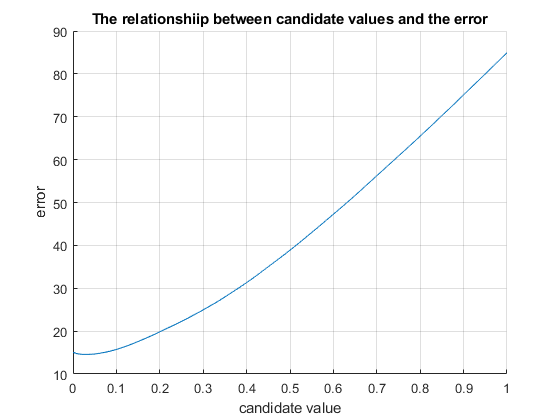

% generate random normally distributed values 
% and raise each value to the 4th power
rndmData = rand(1, 100).^4;

% 100 equally spaced values between 0 and 100 (with step = .0101)
xSpace = linspace(0, 1, 100);

% convert row with random data into a column of values,
% and for each value compute the sum of the absolute diff btwn the value
% and all the dataPoints (linspace)
% {i=1,100: E(|value - dataPoints(i)|)}
errorMetrics = sum(abs(rndmData(:) - xSpace));

figure;
hold on;
grid;
title('The relationshiip between candidate values and the error');
xlabel('candidate value');
ylabel('error');
axis([0 1 10 90]);
plot(xSpace, errorMetrics);

## 3. Generate some random data using `x = rand(1,1000); y = x+0.1*randn(1,1000);`. Using ordinary least-squares (OLS), fit a line to these data and visualize the results.

% generate random data
x = rand(1, 1000);
y = x + .1 * randn(1, 1000);

% we have to fit a model to the generated data
% assume that we know what model to use 
% (the model which was used to generate the data):
% y = ax + b; where a, b - free parameters
% according to the given model: a = 1, b = .1*randn()

% the chosen model is a linearized model -> 
% it can be expressed using simple matrix notation;
% construct the regressor matrix:
X = [x(:) ones(length(x), 1)];

% find the free parameters of the model 
% using OLS estimation (ordinary least-squares):

%{ 
-----explanation-----
x = [x1 x2 ... x1000] - 1*1000
X = [x1 1; x2 1; ...; x1000 1] - 1000*2
X' = [x1 x2 ... x1000; 1 1 ... 1] - 2*1000
w: w * X' = y or (w is a row and y is a row)
w: X * w = y' (w is a column and y is a column)
    X'*X * w = X' * y';
    w = inv(X'*X)*X' * y';
w = [w1; w2] = 2*1
X*inv(X) = inv(X)*X = I - identity matrix.
-----explanation-----
%}

w = inv(X'*X) * X' * y(:);

% display the weights
fprintf('weights for y(x) = a*x + b: [a = %f, b = %f]', w(1), w(2)); 

weights for y(x) = a*x + b: [a = 1.030101, b = -0.012554]

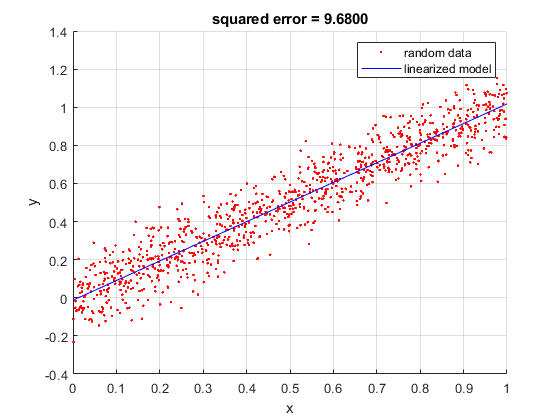


% define the model using weights
yModel = X * w;

% calculate the squared error, achieved by the yModel
sqErr = sum((y' - yModel).^2);

% visualize
figure;
hold on;
grid;
scatter(x, y, 'r.');
% save current axis (for x and y axes)
ax = axis;

% get limits for x ax, divide the interval into 100, convert to column
xM = linspace(ax(1), ax(2), 100)';
yM = [xM ones(length(xM), 1)] * w;
plot(xM, yM, 'b-');
legend('random data', 'linearized model');
xlabel('x');
ylabel('y');
title(sprintf('squared error = %.4f', sqErr));

## 4. Consider the model *y*=*ax*+*b*. Using *a*= 1.3 and *b*= 1, generate some simulated data. Then use nonlinear optimization to fit the model to the data. For a visualization of the search process, download the file `outputfcnplot.m `and pass the options structure `optimset('Display','iter','OutputFcn' @(a,b,c) outputfcnplot(a,b,c,1,y)) `to the optimizer (e.g.`lsqnonlin.m`). (Note that the options structure code assumes that `y `is defined in the workspace and refers to the simulated *y*-values.)

% the model: y = a^x + b;
a = 1.3

a = 1.3000

b = 1;

% generate random data
xx = 0:.01:10;
yy = a.^xx + b + 5 * randn(size(xx));

% we have to fit a model to the generated data

% define optimization options
options = optimset('Display', 'iter', 'FunValCheck', 'on', ...
    'MaxFunEvals', Inf, 'MaxIter', Inf, ...      
    'TolFun', 1e-6, ...
    'OutputFcn', @(a,b,c) outputfcnplot(a,b,c,1,yy));
 
% define bounds for the parameters
%            a       n
paramslb = [0.0     0.0];    % lower bound
paramsub = [inf     inf];   % upper bound

% define the initial seed
%          a       n
params0 = [1.0    1.0];


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality


     0          3         26104.8                      1.31e+04


     1          6         24948.5       0.501522       8.02e+03      


     2          9         24549.1      0.0718316            467      


     3         12         24547.8      0.0189746           34.8      


     4         15         24547.7     0.00855718             11      


     5         18         24547.6     0.00215143           1.61      


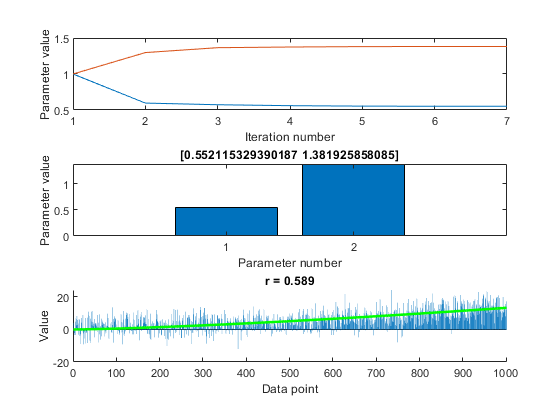


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the selected value of the function tolerance.

<stopping criteria details>



% estimate free parameters of the model (a, b)
% using nonlinear optimization
modelfun = @(pVect, xVect) pVect(1) * xVect.^pVect(2);

% output the predicted values
[params, resnorm, residual, exitflag, output] = ...
    lsqcurvefit(modelfun, params0, xx, yy, paramslb, paramsub, options);


% display the estimated parameters
fprintf('params for y(x) = a^x + b: [a = %f, b = %f]', params(1), params(2));

params for y(x) = a^x + b: [a = 0.552115, b = 1.381926]


% define the model using weights
yyModel = modelfun(params, xx);

% calculate the squared error, achieved by the yModel
% resnorm = value of squared error
sqErrModel = sum((yy' - yyModel').^2);

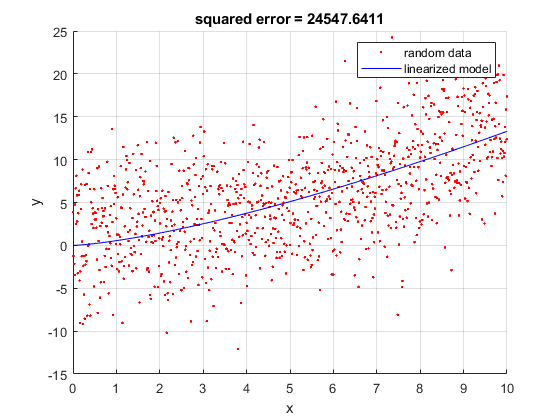

% visualize
figure;
hold on;
grid;
scatter(xx, yy, 'r.');
% save current axis (for x and y axes)
axM = axis;

% get limits for x ax, divide the interval into 100, convert to column
xxM = linspace(axM(1), axM(2), 100)';
yyM = modelfun(params, xxM);
plot(xxM, yyM, 'b-');
legend('random data', 'linearized model');
xlabel('x');
ylabel('y');
%title(sprintf('squared error = %.4f', sqErrModel));
title(sprintf('squared error = %.4f', resnorm));

## 5. Implement one-dimensional nearest-neighbor regression. To do this, first write a function that conforms to the declaration given below. Then, generate and visualize some data (*x-*and *y*-values). Finally, calculate the prediction of the nearest-neighbor regression model for the range of *x*-values shown in the plot and visualize the results.

%{
function yy = nnregress(xx,x,y) 

<xx> is a vector of x-coordinates to evaluate at 
<x> is a vector of x-data 
<y> is a vector of y-data 
%
return a vector with the predictions of a 
nearest-neighbor regression model evaluated 
at the values in <xx>. 
%}